# Cleanup

clearvars
close all
clc

## Generate cuboid beacon

side = 0.5;
points = [-1 -1 1 1 -1 -1 1 1; -1 -1 -1 -1 1 1 1 1; 1 -1 1 -1 1 -1 1 -1] * 0.5 * side + [30; 30; 5];
index_pair = [1 2; 3 4; 5 6; 7 8];
n_points = length(points);
center = mean(points, 2);

## Plot beacon features

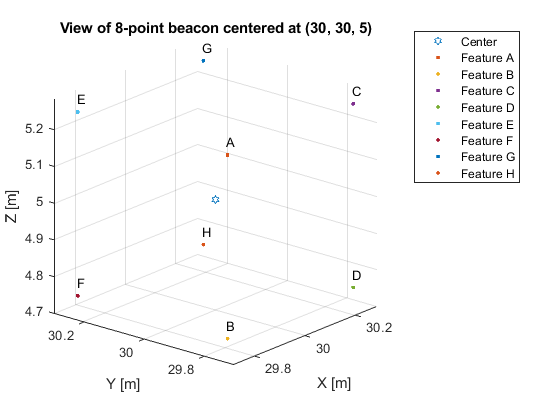

fig = figure('name', 'beacon');
scatter3(center(1), center(2), center(3), 'Marker', 'hexagram', 'DisplayName','Center');
hold on
axis equal
axis padded
view(-50, 20)
for  j = 1:n_points
    scatter3(points(1,j), points(2,j), points(3,j) , 'Marker' , '.', 'DisplayName', "Feature " + char('@'+ j),'LineWidth', 1);
    text(points(1,j) + (side / 20), points(2,j) + (side / 20), points(3,j) + (side / 20), char('@'+ j));
end
title("View of " + n_points + "-point beacon centered at (" + center(1) + ", " + center(2) + ", " + center(3) + ")")
xlabel 'X [m]'
ylabel 'Y [m]'
zlabel 'Z [m]'
legend

## Parameters

r0 = 15;
x0 = center(1);
y0 = center(2) - r0;
z0 = center(3);
N = 13; % N of photos
gamma_E = 0.05; % uniform noise coefficient for E poison
gamma_photo = 0.001; % uniform noise coefficient for photos

## Run Simulink

USE_SIMULINK = true;
radius_tolerance = 0.8; % determines when to start considering circular motion

if ~USE_SIMULINK
    %% Simulate running the script, and you get coords_x,coords_y,thetas as variables
    disp("Generating trajectory manually")
    n_samples = 100;
    thetas = (0:1/n_samples:1 - 1/n_samples) * 360;
    circle = center + [r0 * cos(deg2rad(thetas)); r0 * sin(deg2rad(thetas)); zeros(1, n_samples)];
    seg_coords_x = circle(1, :);
    seg_coords_y = circle(2, :);
    seg_coords_z = center(3) * ones(1, n_samples);
else
    %% Otherwise just filter input data
    disp("Using simulink simulation")
    %run def_trajectory.m
    load data.mat
    coords_x = x_out';
    coords_y = y_out';
    n_samples = length(coords_x);
    %% Find start of circular motion
    for i = 1:n_samples
        curr_norm = norm(coords_x(i), coords_y(i));
        if curr_norm > radius_tolerance * r0
            start_sample = i;
            break;
        end
    end
    coords_x = coords_x + center(1);
    coords_y = coords_y + center(2);
    coords_z = ones(1, n_samples)*center(3);
    thetas = rad2deg(theta_out(start_sample:end))';
    n_samples = length(coords_x) - start_sample + 1;
    seg_coords_x = coords_x(:,start_sample:end);
    seg_coords_y = coords_y(:,start_sample:end);
    seg_coords_z = center(3) * ones(1, n_samples);
end

Using simulink simulation


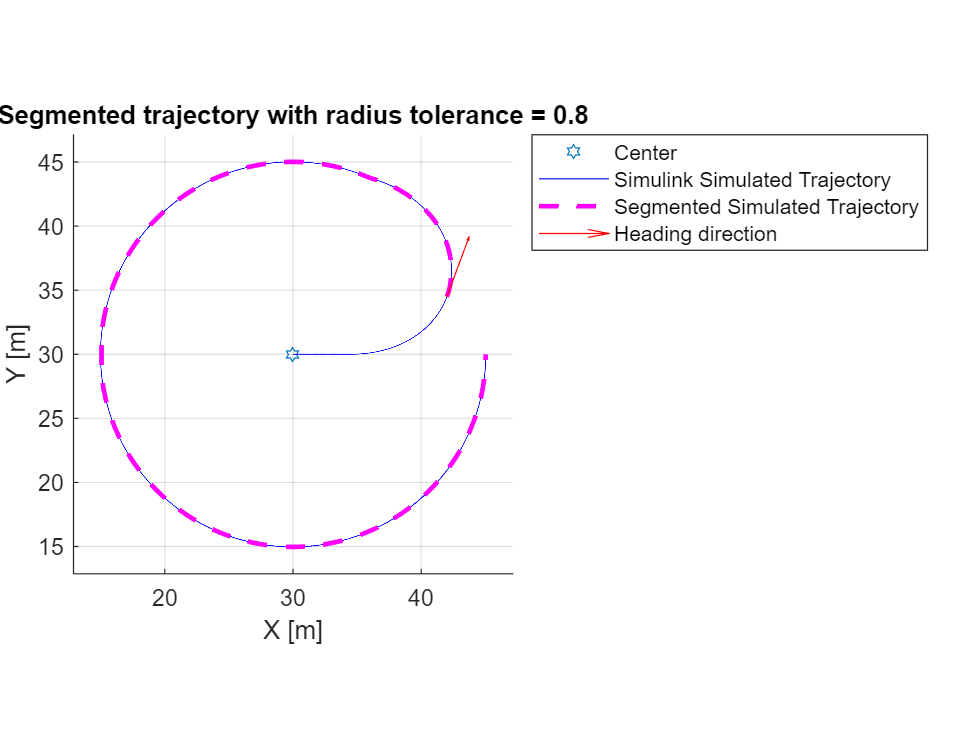

figure
scatter3(center(1), center(2), center(3), 'Marker', 'hexagram', 'DisplayName','Center');
grid on
axis equal
axis padded
hold on
title("Segmented trajectory with radius tolerance = " + radius_tolerance)
if USE_SIMULINK
    plot3(center(1) + x_out', center(2) + y_out', coords_z, "DisplayName", "Simulink Simulated Trajectory","Color","b")
end
plot3(seg_coords_x, seg_coords_y, seg_coords_z, "--", "LineWidth", 2, "DisplayName", "Segmented Simulated Trajectory","Color","m")
sag_versor = [seg_coords_x(2) - seg_coords_x(1); seg_coords_y(2) - seg_coords_y(1); 0];
sag_versor = sag_versor / norm(sag_versor);
quiver3(seg_coords_x(1), seg_coords_y(1), seg_coords_z(1), sag_versor(1), sag_versor(2), sag_versor(3), "Color", "r", "LineWidth", 0.5, ...
    "AutoscaleFactor", 5, "DisplayName", "Heading direction");
view(2)
xlabel 'X [m]'
ylabel 'Y [m]'
zlabel 'Z [m]'
legend

## Get absolute measurements (T, R) from cartesian points

shoots_interval = ceil((n_samples - N)/(N - 1));
saggi_angles = thetas(1:shoots_interval:end);
saggi_angles = wrapTo360(saggi_angles);
T_history_abs = [seg_coords_x(1:shoots_interval:n_samples); seg_coords_y(1:shoots_interval:n_samples); z0 * ones(1,N)];

%% Calculate the pose of camera wrt absolute frame
R_history_abs = zeros(3,3,N);
cam_angles = zeros(1,N);
for i = 1:N
    R_history_abs(:, :, i) = getRfromZ(T_history_abs(:,i), center);
    m = rotm2eul(R_history_abs(:,:,i));
    cam_angles(i) = wrapTo360(rad2deg(m(1)) + 90);
end
delta_cam_sag = wrapTo360(cam_angles - saggi_angles);

## Trajectory parameters

Rwb = R_history_abs(:,:,1); % Initial pose of camera (body 2 word)
Rbw = Rwb'; % Initial pose of camera (word 2 body)
Twb = T_history_abs(:,1,1); % Initial position of camera
Tbw = -Twb;

## Initial position plot

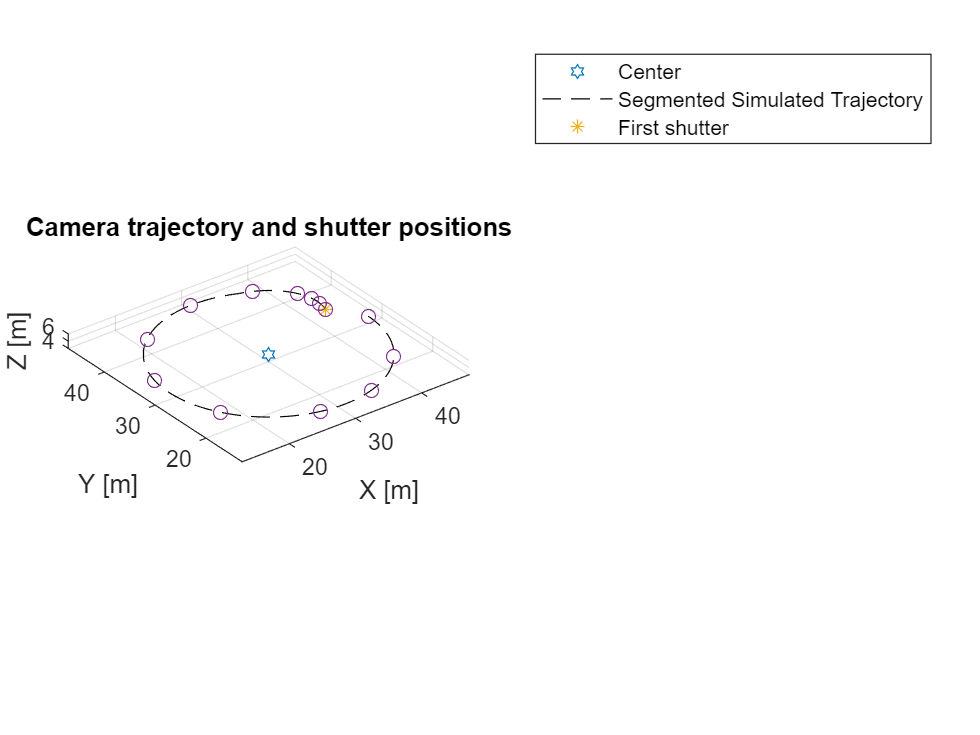

figure
hold on
scatter3(center(1), center(2), center(3), 'Marker', 'hexagram', 'DisplayName','Center');
plot3(seg_coords_x, seg_coords_y, seg_coords_z, "--", "LineWidth", 0.5, "DisplayName", "Segmented Simulated Trajectory","Color","k")
scatter3(Twb(1), Twb(2), Twb(3), 'Marker',"*", 'DisplayName','First shutter')
scatter3(T_history_abs(1,:), T_history_abs(2,:), T_history_abs(3,:), "Marker", "o", "HandleVisibility","off")
view(3)
grid on
axis equal
axis padded
xlabel 'X [m]'
ylabel 'Y [m]'
zlabel 'Z [m]'
title("Camera trajectory and shutter positions");
view(3)
legend

## Trajectory generation and plotting

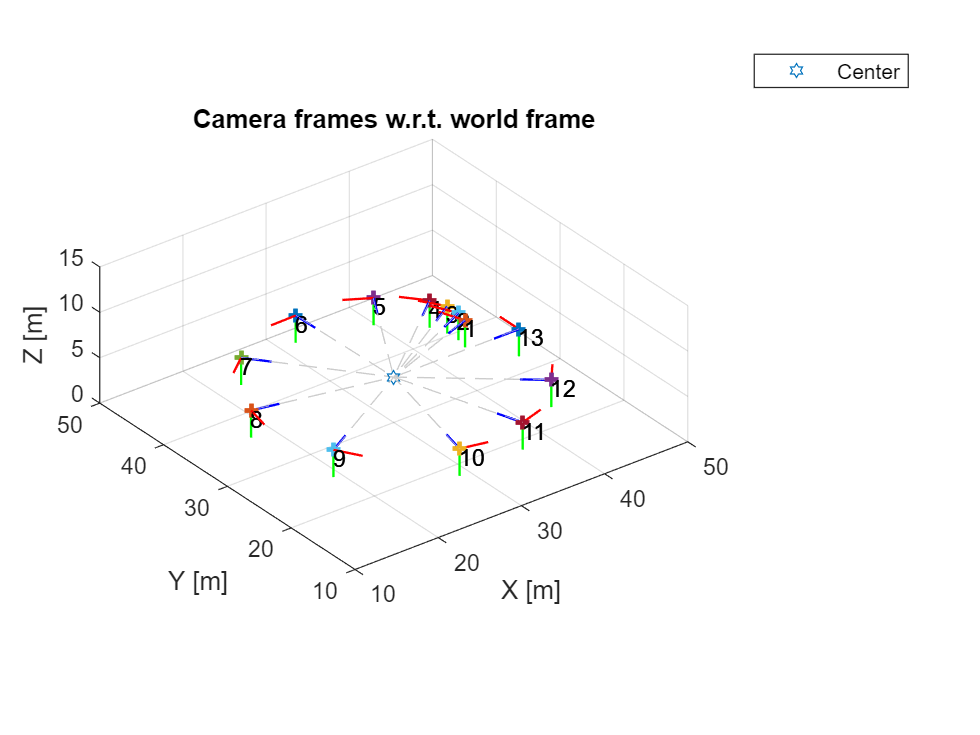

figure
hold on
scatter3(center(1), center(2), center(3), 'Marker', 'hexagram', 'DisplayName','Center');
for i = 1:N
    R0i = R_history_abs(:,:,i);
    T0i = T_history_abs(:,i);
    scatter3(T0i(1) , T0i(2) , T0i(3) , 'Marker' , '+', 'HandleVisibility','off', "LineWidth", 2);
    text(T0i(1) - [0.5 0.5 0.5], T0i(2) - [0.5 0.5 0.5], T0i(3) - [0.5 0.5 0.5], "" + i);
    line([T0i(1) center(1)], [T0i(2) center(2)], [T0i(3) center(3)], 'LineStyle','--', "Color", [.8, .8, .8], 'HandleVisibility','off', 'LineWidth', 0.15);
    triad('Parent',gca,'Scale',3,'LineWidth',1,'Tag',"#" + i ,'Matrix', [R0i T0i; 0 0 0 1]);
end
zlim([0 15])
view(3)
daspect([1 1 1])
grid on
xlabel 'X [m]'
ylabel 'Y [m]'
zlabel 'Z [m]'
title("Camera frames w.r.t. world frame");
legend

## Generate E from R and T (until we can figure out E estimation)

E_history = zeros(3,3,N,N); % create a cell array equal to the number of poses
EN_history = zeros(3,3,N,N); % same for noisy E
GT_rel_T = zeros(3,1,N,N);
GT_rel_T_norm = zeros(3,1,N,N);
GT_rel_R = zeros(3,3,N,N);

for i = 1:N
    for j = 1:N
        if j == i
            GT_rel_R(:,:, i, j) = eye(3);
            GT_rel_T(:,:, i, j) = zeros(3,1);
            continue
        else
            R_ij = axang2rotm([0 1 0 deg2rad(cam_angles(j) - cam_angles(i))]);
        end
        T_ij = T_history_abs(:, j) - T_history_abs(:, i);
        %T_ij = Rij * T_history_abs(:, j) - T_history_abs(:, i);
        E = getSkew(T_ij) * R_ij;
        GT_rel_T(:,:, i, j) = T_ij;
        GT_rel_T_norm(:, :, i, j) = T_ij / norm(T_ij);
        GT_rel_R(:,:, i, j) = R_ij;
        E = E / norm(E); % normalize to lose scale
        E_noisy = E + gamma_E*rand(3, 3); % poison E matrix with noise to simulate reconstruction error
        E_history(:,:, i, j) = E;
        EN_history(:,:, i, j) = E_noisy;
    end
end

## Compute R, T from E

R1_rel = zeros(3,3,N,N);
T1_rel = zeros(3,1,N,N);
R2_rel = zeros(3,3,N,N);
T2_rel = zeros(3,1,N,N);

for i = 1:N
    for j = 1:N
        if i == j; continue; end
        %Compute R_ij and T_ij
        %E = E_history(:,:, i, j); % Extract E_ij
        E = EN_history(:,:, i, j); % Uncomment to to use noisy
        [U, S, V] = svd(E); % Singular value decomp
        % Safeguard against non SO(3) matrix
        if (det(U)<0)
            U = [U(:,1) U(:,2) -U(:,3)];
        end
        if (det(V)<0)
            V = [V(:,1) V(:,2) -V(:,3)]; 
        end
        sigmas = diag(S); % Get singular values
        avg = (sigmas(1) + sigmas(2)) / 2; % Average values
        sigmas = [avg; avg; 0]; % Substitute
        S = diag(sigmas);
        Rp = [cos(pi/2) -sin(pi/2) 0; sin(pi/2) cos(pi/2) 0; 0 0 1]; % Rotation of pi/2 around z axis
        Rm = [cos(-pi/2) -sin(-pi/2) 0; sin(-pi/2) cos(-pi/2) 0; 0 0 1]; % Rotation of -pi/2 around z axis
        skewT1 = U * Rp * S * U'; % Get T matrix
        currT1 = getT(skewT1); % Get T from T matrix
        currT2 = -getT(skewT1);
        currR1 = U * Rp' * V'; % Get R matrix
        currR2 = U * Rm' * V';
        R1_rel(:,:, i, j) = currR1; % Save data
        T1_rel(:,:, i, j) = currT1;
        R2_rel(:,:, i, j) = currR2;
        T2_rel(:,:, i, j) = currT2;
    end
end

## Perspective projection of points (photos simulation)

PI0 = [eye(3) zeros(3,1)]; % standard projection matrix
K_f = eye(3); % unitary focal length
K_s = [1 0 0; 0 1 0; 0 0 1]; % ideal, no distortion
K = K_s * K_f;
im_planes_norm = zeros(3, n_points, N); % normalized points for each view
im_planes_noisy = zeros(3, n_points, N); % noisy normalized points for each view (actual photos)
centers_norm = zeros(3, N);
centers_noisy = zeros(3,N);

for i = 1:N
    f = figure('name', "photo" + i);
    R0i = R_history_abs(:, :, i);
    T0i = T_history_abs(:, i);
    Ri0 = R0i';
    Ti0 = -T0i;
    g = [Ri0 Ri0*Ti0; 0 0 0 1];
    proj_c_og = K * PI0 * g * [center; 1];
    proj_c_norm = proj_c_og / proj_c_og(3);
    centers_norm(:, i) = proj_c_norm;
    centers_noisy(:, i) = proj_c_norm + [gamma_photo * rand(2,1); 0];
    scatter(proj_c_norm(1), proj_c_norm(2), 200, "Marker", "hexagram");
    text(proj_c_norm(1), proj_c_norm(2), "C", "Fontsize", 8, "HorizontalAlignment","center","FontWeight","bold");
    hold on
    grid on
    axis padded
    xlabel 'X [m]'
    ylabel '-Y [m]'
    for j = 1:n_points
        im_point = K * PI0 * g * [points(:,j); 1];
        im_planes_norm(:, j, i) = im_point / im_point(3);
        im_planes_noisy(:, j, i) = im_point / im_point(3) + [gamma_photo*rand(2,1); 0];
        scatter(im_planes_noisy(1, j, i), im_planes_noisy(2, j, i), 36, "Marker", ".");
        scatter(im_planes_norm(1, j, i), im_planes_norm(2, j, i), 90, "Marker", "square");
        text(im_planes_norm(1, j, i), im_planes_norm(2, j, i), char('@'+ j), "Fontsize", 8, "HorizontalAlignment","center");
    end
    title("Image on pose #" + i);
    set(gca, 'YDir','reverse')
    close(f)
end

## Reconstruct camera distance from beacon center (rotation center) for each photo (cuboid case)

est_dist = zeros(N,1);
for i = 1:N
    AB_3D = norm(points(:, 2) - points(:,1));
    CD_3D = norm(points(:, 4) - points(:,3));
    EF_3D = norm(points(:, 6) - points(:,5));
    GH_3D = norm(points(:, 8) - points(:,7));
    AB = norm(im_planes_noisy(:,2,i)- im_planes_noisy(:,1,i));
    CD = norm(im_planes_noisy(:,4,i)- im_planes_noisy(:,3,i));
    EF = norm(im_planes_noisy(:,6,i)- im_planes_noisy(:,5,i));
    GH = norm(im_planes_noisy(:,8,i)- im_planes_noisy(:,7,i));
    Z_AB = AB_3D / AB;
    Z_CD = CD_3D / CD;
    Z_EF = EF_3D / EF;
    Z_GH = GH_3D / GH;
    Z_CENTER = mean([Z_AB, Z_CD, Z_EF, Z_GH]);
    est_dist(i) = Z_CENTER;
end

for j = 1:N
    cum_sum = 0;
    for i = 1:length(index_pair)
        index_A = index_pair(i, 1);
        index_B = index_pair(i, 2);
        AB_3D = norm(points(:,index_B) - points(:,index_A));
        AB_2D = norm(im_planes_norm(:,index_A,j)- im_planes_norm(:,index_B,j));
        Z_AB = AB_3D / AB_2D;
        cum_sum = cum_sum + Z_AB;
    end
    cum_sum;
    est_dist(j) = cum_sum / length(index_pair);
end
est_r0 = mean(est_dist);
est_center = [x0; y0 + est_r0; z0];

## Pose discrimination via triangulation

cam = cameraParameters("IntrinsicMatrix", K);
R_rel = zeros(3,3,N,N);
T_rel = zeros(3,1,N,N);
for i = 1:N
    for j = 1:N
        if i == j
            R_rel(:, :, i, j) = eye(3);
            R1_rel(:, :, i, j) = eye(3);
            R2_rel(:, :, i, j) = eye(3);
            T_rel(:, :, i, j) = zeros(3,1);
            T1_rel(:, :, i, j) = zeros(3,1);
            T2_rel(:, :, i, j) = zeros(3,1);
            continue
        end
        best = 0;
        % Case 1 R1 T1
        % Extract R12 and T12 matrices
        R = R1_rel(:,:, i, j);
        T = T1_rel(:,:, i, j);
        % Configure foward extrinsic
        P1 = K * PI0 * [eye(3) zeros(3,1); 0 0 0 1];
        P2 = K * PI0 * [R' -R' * T; 0 0 0 1];
        % Triangulate points in frame 1
        pnts = triangulate(im_planes_norm(1:2,:,i)', im_planes_norm(1:2,:,j)', P1', P2');
        % Count positive occurences in z for both
        votes = nnz((double(pnts(:,3)) > 0) == 1);
        % If better result than previous
        if votes > best
            % Update best result
            best = votes;
            %fprintf("Filled cell [%i,%i] with %i/%i votes\n", i, j, best, n_points);
            % Save R12, T12 as correct
            R_rel(:,:, i, j) = R;
            T_rel(:,:, i, j) = T;
        end
        % Case 2 R1 T2
        R = R1_rel(:,:, i, j);
        T = T2_rel(:,:, i, j);
        P1 = K * PI0 * [eye(3) zeros(3,1); 0 0 0 1];
        P2 = K * PI0 * [R' -R' * T; 0 0 0 1];
        % Triangulate points in frame
        pnts = triangulate(im_planes_norm(1:2,:,i)', im_planes_norm(1:2,:,j)', P1', P2');
        % Count positive occurences in z for both
        votes = nnz((double(pnts(:,3)) > 0) == 1);
        if votes > best
            best = votes;
            %fprintf("Filled cell [%i,%i] with %i/%i votes\n", i, j, best, n_points);
            R_rel(:,:, i, j) = R;
            T_rel(:,:, i, j) = T;
        end
        % Case 3 R2 T1
        R = R2_rel(:,:, i, j);
        T = T1_rel(:,:, i, j);
        P1 = K * PI0 * [eye(3) zeros(3,1); 0 0 0 1];
        P2 = K * PI0 * [R' -R' * T; 0 0 0 1];
        % Triangulate points in frame
        pnts = triangulate(im_planes_norm(1:2,:,i)', im_planes_norm(1:2,:,j)', P1', P2');
        % Count positive occurences in z for both
        votes = nnz((double(pnts(:,3)) > 0) == 1);
        if votes > best
            best = votes;
            %fprintf("Filled cell [%i,%i] with %i/%i votes\n", i, j, best, n_points);
            R_rel(:,:, i, j) = R;
            T_rel(:,:, i, j) = T;
        end
        % Case 4 R2 T2
        R = R2_rel(:,:, i, j);
        T = T2_rel(:,:, i, j);
        P1 = K * PI0 * [eye(3) zeros(3,1); 0 0 0 1];
        P2 = K * PI0 * [R' -R' * T; 0 0 0 1];
        % Triangulate points in frame
        pnts = triangulate(im_planes_norm(1:2,:,i)', im_planes_norm(1:2,:,j)', P1', P2');
        % Count positive occurences in z for both
        votes = nnz((double(pnts(:,3)) > 0) == 1);
        if votes > best
            best = votes;
            %fprintf("Filled cell [%i,%i] with %i/%i votes\n", i, j, best, n_points);
            R_rel(:,:, i, j) = R;
            T_rel(:,:, i, j) = T;
        end
    end
end

## Discriminate pose manually

for i = 1:N
    for j = 1:N
        R1 = R1_rel(:,:,i,j);
        R2 = R2_rel(:,:,i,j);
        RGT = GT_rel_R(:,:,i,j);
        if norm(R1 - RGT, 'fro') >= norm(R2 - RGT, 'fro')
            R_rel(:,:,i,j) = R2;
        else
            R_rel(:,:,i,j) = R1;
        end
        T1 = T1_rel(:,:,i,j);
        T2 = T2_rel(:,:,i,j);
        TGT = GT_rel_T_norm(:,:,i,j);
        if norm(T1 - TGT) >= norm(T2 - TGT)
            T_rel(:,:,i,j) = T2;
        else
            T_rel(:,:,i,j) = T1;
        end
    end
end

## Sanity check

% Take only first row for each table
est_T = reshape(T_rel(:,:,1,:), 3, N);
est_T1 = reshape(T1_rel(:,:,1,:), 3, N);
est_T2 = reshape(T2_rel(:,:,1,:), 3, N);
T = reshape(GT_rel_T_norm(:,:,1,:), 3, N);

wrongfT = abs(est_T - T) > 1e-1;
af = zeros(N,N);
aGT = zeros(N,N);

for i = 1:N
    for j = 1:N
        af(i,j) = getYangle(R_rel(:,:,i,j));
        aGT(i,j) = getYangle(GT_rel_R(:,:,i,j));
    end
end

wrongfR = wrapTo360(abs(af - aGT)) > 180;
if ~(wrongfT > 0)
    disp("Correct T direction discrimination up to 0.1")
else
    disp("Not within margin of error of 0.1")
end

Correct T direction discrimination up to 0.1


if ~(wrongfR > 0)
    disp("Correct R discrimination up to 5 degrees")
else 
    disp("Not within margin of error of 5 degrees")
end

Correct R discrimination up to 5 degrees


af;
aGT;
angle_err = abs(af - aGT)

angle_err =          0    2.4999    1.4766    1.6024    1.7436    0.2981    1.4872    2.3686    3.7101    2.6659    1.1816    0.7987    1.1966
    1.5392         0    0.8163    1.4382    0.9659    2.2671    2.5849    1.1280    3.4781    4.2673    1.0768    0.7803    0.3063
    1.8320    1.6483         0    0.5435    1.8605    1.7229    4.5169    3.0265    1.2078    1.4097    1.4457    0.1393    0.2035
    0.6997    0.9157    2.1391         0    3.0305    3.6370    3.0761    2.5494    3.3378    3.2237    0.1266    0.9525    1.7753
    1.3605    1.3510    1.1105    0.2591         0    3.5235    4.1116    2.7760    2.9459    1.4734    1.6830    0.4027    1.4367
    0.9079    2.6036    0.7131    0.1672    1.4190         0    3.6432    1.2127    0.7244    1.8506    1.2034    1.3108    2.1918
    0.3596    1.8079    0.3111    1.7960    1.2614    2.0826         0    1.8720    0.2546    0.8897    2.2337    2.6554    2.5223
    0.0594    0.2527    0.8664    0.3225    2.7481    1.3210    1.6085 

## Filter R using symmetry

%% Initial filtering of T based on the fact that we expect a symmetric table
up = triu(af);
low = -tril(af)';
tot = (up + low) / 2;
af_sym = tot - tot';
angle_err = abs(af_sym - aGT)

angle_err =          0    2.0195    1.6543    1.1510    1.5521    0.3049    0.9234    1.2140    2.9478    1.7821    0.3089    0.9823    1.6472
    2.0195         0    1.2323    1.1770    1.1585    0.1683    0.3885    0.6903    3.6337    2.5217    0.4092    0.8792    1.2680
    1.6543    1.2323         0    1.3413    1.4855    0.5049    2.1029    1.9465    2.1376    1.8504    0.8905    0.3412    0.4769
    1.1510    1.1770    1.3413         0    1.3857    1.9021    0.6401    1.1135    1.8366    2.9481    0.7821    0.5121    0.7736
    1.5521    1.1585    1.4855    1.3857         0    2.4712    1.4251    2.7620    2.8920    1.5778    1.5773    0.0372    0.4061
    0.3049    0.1683    0.5049    1.9021    2.4712         0    2.8629    1.2668    0.9080    1.4806    1.3281    1.9946    1.0603
    0.9234    0.3885    2.1029    0.6401    1.4251    2.8629         0    1.7403    0.4140    1.2998    2.1362    2.6767    2.1490
    1.2140    0.6903    1.9465    1.1135    2.7620    1.2668    1.7403 

## Scale T_rel using Carnot

T_scaled_rel = zeros(3,1,N,N);
T_scaled_rel_sym = zeros(3,1,N,N);
for i = 1:N
    for j = 1:N
        % Cosine theorem
        c = sqrt(est_dist(i) ^ 2 + est_dist(j) ^ 2 - 2 * est_dist(i) * est_dist(j) * cos(deg2rad(af_sym(i,j))));
        T_scaled_rel(:,:,i,j) = c * T_rel(:,:,i,j);
        T_scaled_rel(3,:,i,j) = 0;
    end
end

## Filter T using simmetry

TX = reshape(T_scaled_rel(1, :, :, :), N, N);
TXU = triu(TX);
TXL = tril(TX);
TXU = (TXU - TXL') / 2;
TXL = -TXU';
TX = TXU + TXL;
TY = reshape(T_scaled_rel(2, :, :, :), N, N);
TYU = triu(TY);
TYL = tril(TY);
TYU = (TYU - TYL') / 2;
TYL = -TYU';
TY = TYU + TYL;
TX = reshape(TX, 1, 1, N, N);
TY = reshape(TY, 1, 1, N, N);
T_scaled_rel_sym(1, :, :, :) = TX;
T_scaled_rel_sym(2, :, :, :) = TY;

## Filter T using odometer approach

%% Under the hypotesys of no slipping, and counting the distance between photos in a circular motion
odom = 0;
odom_est = 0;
T_scaled_rel_odom = zeros(3,1,N,N);
for i = 1:N-1
    pseudo_r0 = (est_dist(i + 1) + est_dist(i)) / 2;
    curr_dist_clean = abs(pseudo_r0 * deg2rad(af_sym(i, i + 1)));
    curr_dist_est = norm(T_scaled_rel(:,:, i, i + 1));
    ratio = curr_dist_clean / curr_dist_est;
    T_scaled_rel_odom(:,:,i, i + 1) = ratio * T_scaled_rel(:,:, i, i + 1);
    odom_est = odom_est + curr_dist_est;
    odom = odom + curr_dist_clean;
end

## Calculate Trajectories

est_cw = zeros(3, N);
est_ccw = zeros(3, N);
est_sym = zeros(3, N);
est_odom = zeros(3, N);
est_ccw(:, 1) = T_history_abs(:, 1);
est_cw(:, end) = T_history_abs(:, end);
est_sym(:, 1) = T_history_abs(:, 1);
est_odom(:, 1) = T_history_abs(:, 1);
currP_ccw = T_history_abs(:, 1);
currP_cw = T_history_abs(:, end);
currP_sym = T_history_abs(:, 1);
currP_odom = T_history_abs(:,1);

for i = 1:N-1
    if i == N
        j = 1;
    else 
        j = i + 1;
    end
    nextP_sym = currP_sym + T_scaled_rel_sym(:,:,i, j);
    est_sym(:, i + 1) = nextP_sym;
    currP_sym = nextP_sym;
end

for i = 1:N-1
    if i == N
        j = 1;
    else 
        j = i + 1;
    end
    nextP_ccw = currP_ccw + T_scaled_rel(:,:,i, j);
    est_ccw(:, i + 1) = nextP_ccw;
    currP_ccw = nextP_ccw;
end

for i = 1:N-1
    if i == N
        j = 1;
    else 
        j = i + 1;
    end
    nextP_odom = currP_odom + T_scaled_rel_odom(:,:,i, j);
    est_odom(:, i + 1) = nextP_odom;
    currP_odom = nextP_odom;
end

for j = N-1:-1:1
    if j == N
        i = 1;
    else 
        i = j + 1;
    end
    nextP_cw = currP_cw + T_scaled_rel(:,:,i, j); 
    est_cw(:, j) = nextP_cw;
    currP_cw = nextP_cw;
end

## Weighted average of clockwise and counterclockwise

w = N-1:-1:1; % linear weighting
w = [w 0];
w = w / max(w);
w1 = w.*est_ccw;
w2 = flip(w).*est_cw;
est_avg =(w1 + w2);

## Plot trajectory

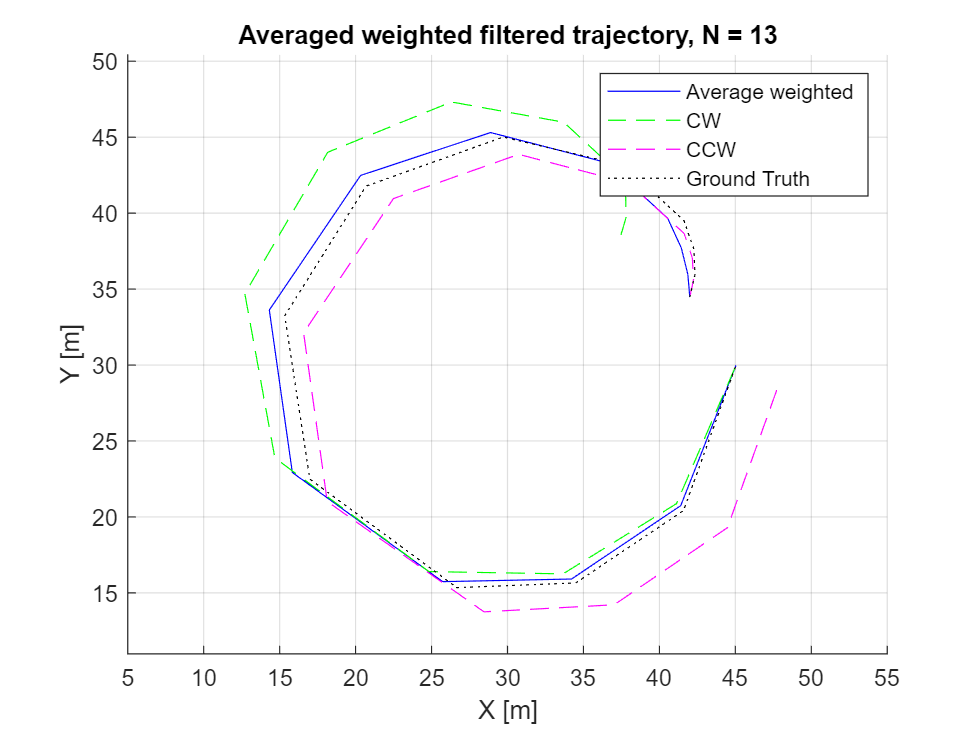

figure
hold on
axis equal
axis padded
grid on
xlabel 'X [m]'
ylabel 'Y [m]'
title("Averaged weighted filtered trajectory, N = " + N)
plot3(est_avg(1, :), est_avg(2, :), est_avg(3, :), "DisplayName", "Average weighted", "Color", "b")
plot3(est_cw(1, :), est_cw(2, :), est_cw(3, :), "DisplayName", "CW", "Color", "g", "Linestyle", "--")
plot3(est_ccw(1, :), est_ccw(2, :), est_ccw(3, :), "DisplayName", "CCW", "Color", "m", "Linestyle", "--")
plot3(T_history_abs(1, :), T_history_abs(2, :), T_history_abs(3, :), "DisplayName", "Ground Truth", "Color", "k", "Linestyle", ":")
legend
view(2)

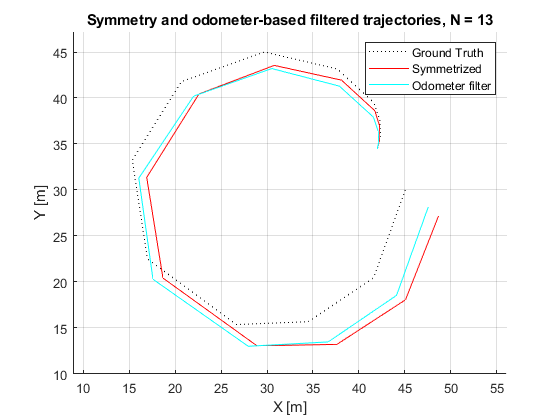

figure
hold on
axis equal
axis padded
grid on
xlabel 'X [m]'
ylabel 'Y [m]'
title("Symmetry and odometer-based filtered trajectories, N = " + N)
plot3(T_history_abs(1, :), T_history_abs(2, :), T_history_abs(3, :), "DisplayName", "Ground Truth", "Color", "k", "Linestyle", ":")
plot3(est_sym(1, :), est_sym(2, :), est_sym(3, :), "DisplayName", "Symmetrized", "Color", "r", "Linestyle", "-")
plot3(est_odom(1, :), est_odom(2, :), est_odom(3, :), "DisplayName", "Odometer filter", "Color", "c", "Linestyle", "-")
legend
view(2)

## Save data

save(num2str(N,'%04.f') + "_trajectories", "est_avg", "est_cw", "est_ccw", "est_sym", "est_odom", "T_history_abs")

## Functions

function alpha = getYangle(R)
    alpha = wrapTo180(rad2deg(atan2(R(3,1), R(1,1))));
end

function R = getRfromZ(T, center)
    z_versor = center - T;
    z_versor = z_versor / norm(z_versor);
    y_versor = [0 0 -1];
    x1_versor = cross(y_versor, z_versor);
    r11 = dot(x1_versor, [1 0 0]);
    r21 = dot(x1_versor, [0 1 0]);
    r31 = dot(x1_versor, [0 0 1]);
    r12 = dot(y_versor, [1 0 0]);
    r22 = dot(y_versor, [0 1 0]);
    r32 = dot(y_versor, [0 0 1]);
    r13 = dot(z_versor, [1 0 0]);
    r23 = dot(z_versor, [0 1 0]);
    r33 = dot(z_versor, [0 0 1]);
    R = [r11 r12 r13; r21 r22 r23; r31 r32 r33];
end